# *frames* package

The **frames** package contains classes to handle operations on homogeneous data matrices that are referenced by column and index identifiers.

There are currently no tool in Matlab to do that. Matlab's (time)tables have row and column names, but do not provide simple operations like addition (table1+table2 is not possible). Matlab's native matrices are not aware of row and column names. When data represents observations of variables, it is always tricky to make sure the data is not misaligned.

The package currently requires a version of **Matlab R2021a** or later.

## Frame classes

The class **frames.DataFrame** and its child class **frames.TimeFrame** provide a data type suitable when working with data sets that are *homogeneous and with column and row names*, making operations on and between Frames simple and robust.

The main properties of these classes are:

- data: TxN, homogeneous data

- index: Tx1

- columns: 1xN

- t: dependent table built on the properties above.

*columns* and *index* are expected to have unique elements. *columns* allows duplicates but issues a warning if it is the case. *index* does not accept duplicates. Moreover, for TimeFrame, *index* is a chronological datetime array.

The Frames are displayed as a table (DataFrame) and as a timetable (TimeFrame).

For the documentation, run

doc frames.DataFrame
doc frames.TimeFrame

## Constructor

Construct a Frame as follows:

% Example:
df = frames.DataFrame([1 2;3 4],[1 2],["col1","col2"])

df =          col1    col2
         ____    ____

    1     1       2  
    2     3       4  


or with a TimeFrame

tf = frames.TimeFrame([1 2;3 4],[738336,738337],["ts1","ts2"])

tf =        Time        ts1    ts2
    ___________    ___    ___

    29-Jun-2021     1      2 
    30-Jun-2021     3      4 


To view the properties of the object, type

details(df)

  2×2 frames.DataFrame array with properties:

           data: [2×2 double]
          index: [2×1 double]
        columns: ["col1"    "col2"]
           name: ""
              t: [2×2 table]
      rowseries: 0
      colseries: 0
    description: ""

  Methods



One can see the properties we have just set in the constructor. The other properties (some of which can be set in the constructor with named arguments) are presented further below.

## Properties Access and Modification

The properties can be accessed simply by

df.data

ans =      1     2
     3     4


df.columns

ans = 1×2 string array
    "col1"    "col2"


They can also be modified

df.data(1,1) = 10;
df.columns = ["a","b"]

df =          a     b
         __    _

    1    10    2
    2     3    4


Frame will throw an error if the data entered are not coherent, e.g. the size is the matching the rest of the data:

try
    df.columns = ["a","b","c"]
catch me
    disp(me.message)
end

columns do not have the same size as data


Or an example with an attempt to assign a duplicate index:

try
    df.index = [1 1]
catch me
    disp(me.message)
end

Invalid argument at position 2. Value must be a unique vector or a frames.UniqueIndex.


## Sub-Frame Access and Modification

% Selection
df(1,:)

ans =          a     b
         __    _

    1    10    2


% same as
df.loc(1,:);
df(1);
df.loc(1);

% Modification
df(1,:) = 10

df =          a     b 
         __    __

    1    10    10
    2     3     4


% Or df.loc(1,:) = 10

One can also drop a column/row with the empty assignment

tmp = df;
tmp(:,"b") = []

tmp =          a 
         __

    1    10
    2     3


df{1:end,2}

ans =          b 
         __

    1    10
    2     4


% same as
df{:,2};
df.iloc(:,2);

df{2,1} = 20

df =          a     b 
         __    __

    1    10    10
    2    20     4


% or df.iloc(2,1) = 20

df.data = [1 2;3 4];  % reset data to original example

## Operations

Frames can be used like matrices for operations.

element-wise operation

df + df

ans =          a    b
         _    _

    1    2    4
    2    6    8


element-wise operation with a non-Frame 

1 + df

ans =          a    b
         _    _

    1    2    3
    2    4    5


transpose and matrix operation

df' * df

ans =          a     b 
         __    __

    a    10    14
    b    14    20


vector = frames.DataFrame([1;2],["a","b"],"vectorColumn");
df * vector

ans =          vectorColumn
         ____________

    1          5     
    2         11     


If Frames are not aligned, an element-wise operation will return an error:

df2 = frames.DataFrame(1,[1 2],["noMatch1","noMatch2"]);
try
    df ./ df2
catch me
    disp(me.message)
end

Frames have different columns!


For element-wise vector operations, only one dimension is needed to be checked for right or wrong alignement.

To do so, one needs to set the *series property* of the vector Frame to true. There are two series properties available, *.rowseries*, and *.colseries*, depending on whether the Frame is a row or column vector.

If the property is not set, the operation fails:

seriesBad = frames.DataFrame([1;2],[1 2],"seriesColumn");
try
    df .* seriesBad
catch me 
    disp(me.message)
end

Frames have different columns!


Make it work by making the Frame a Series

series = seriesBad.asColSeries();
% or series = frames.DataFrame([1;2],[1 2],"seriesColumn",ColSeries=true);
details(series)

  2×1 frames.DataFrame array with properties:

           data: [2×1 double]
          index: [2×1 double]
        columns: "seriesColumn"
           name: ""
              t: [2×1 table]
      rowseries: 0
      colseries: 1
    description: ""

  Methods



df .* series

ans =          a    b
         _    _

    1    1    2
    2    6    8


## Concatenation

One can concatenate different Frames into one with the operator [].

The concatenation can be horizontal or vertical. The operation will align the Frames by expanding (unifying) their index or columns if they are not equal, inserting missing values in the expansion.

tf1 = frames.TimeFrame(1,frames.TimeIndex(["25-Jun-2021","27-Jun-2021","28-Jun-2021"]),["ts1","ts2"]);
tf2 = frames.TimeFrame(2,frames.TimeIndex(["26-Jun-2021","27-Jun-2021","30-Jun-2021"]),"ts3");
[tf1, tf2]

ans =        Time        ts1    ts2    ts3
    ___________    ___    ___    ___

    25-Jun-2021      1      1    NaN
    26-Jun-2021    NaN    NaN      2
    27-Jun-2021      1      1      2
    28-Jun-2021      1      1    NaN
    30-Jun-2021    NaN    NaN      2


tf3 = frames.TimeFrame(2,frames.TimeIndex(["29.06.2021","30.06.2021"],Format="dd.MM.yyyy"),["ts2","ts3"]);
[tf1; tf3]

ans =        Time        ts1    ts2    ts3
    ___________    ___    ___    ___

    25-Jun-2021      1     1     NaN
    27-Jun-2021      1     1     NaN
    28-Jun-2021      1     1     NaN
    29-Jun-2021    NaN     2       2
    30-Jun-2021    NaN     2       2


## Particular use of Index

The type of *index* can be specified, as one may have noticed in the example above.

By default, in DataFrame, the object underlying the index is a *frames.UniqueIndex*, and in TimeFrame, it is a *frames.TimeIndex*. The former requires unique elements, while the latter requires chronological unique time elements.

TimeFrame only accepts a TimeIndex, while DataFrame accepts UniqueIndex, TimeIndex, and SortedIndex (unique and sorted).

The distinction between the different Index impacts the operations of selection, modification, and alignment/concatenation.

% Selection
df.getIndex_()  % gets the underlying Index object

ans =   UniqueIndex with properties:

         name: "Row"
        value: [2×1 double]
    singleton: 0


df([2 1])

ans =          a    b
         _    _

    2    3    4
    1    1    2


dfSorted = df.setIndexType("sorted");
dfSorted.getIndex_()

ans =   SortedIndex with properties:

         name: "Row"
        value: [2×1 double]
    singleton: 0


try
    dfSorted([2 1])
catch me
    disp(me.message)
end

Index is not sorted.


Alignment

df1 = frames.DataFrame([1 3]',[1 3],1);
df2 = frames.DataFrame([2 3]',[2 3],2);
unsortedConcatenation = [df1,df2]

unsortedConcatenation =          x1     x2 
         ___    ___

    1      1    NaN
    3      3      3
    2    NaN      2


df1 = frames.DataFrame([1 3]',frames.SortedIndex([1 3]),1);
df2 = frames.DataFrame([2 3]',frames.SortedIndex([2 3]),2);
sortedConcatenation = [df1,df2]

sortedConcatenation =          x1     x2 
         ___    ___

    1      1    NaN
    2    NaN      2
    3      3      3


**TimeIndex** can read several kinds of arguments: datenum, datetime, and strings/cell together with a Format

frames.TimeIndex(738336)

ans =   TimeIndex with properties:

       format: "dd-MMM-yyyy"
         name: "Time"
        value: 29-Jun-2021
    singleton: 0


frames.TimeIndex(datetime(738336,'ConvertFrom','datenum',Format='dd-MMM-yyyy'));
frames.TimeIndex("29-Jun-2021",Format="dd-MMM-yyyy");

When used in a Frame (used by default in a TimeFrame), one can select a sub-Frame using a *timerange*

tf = frames.TimeFrame((1:6)',738331:738336)  % turns 738331:738336 into a TimeIndex

tf =        Time        Var1
    ___________    ____

    24-Jun-2021     1  
    25-Jun-2021     2  
    26-Jun-2021     3  
    27-Jun-2021     4  
    28-Jun-2021     5  
    29-Jun-2021     6  


tf(timerange(-inf,datetime(738333,'ConvertFrom','datenum'),'closed'));
% This can also be easily written using a string as follows
% tf("dateStart:dateEnd:dateFormat")
tf("-inf:26*06*2021:dd*MM*yyyy")

ans =        Time        Var1
    ___________    ____

    24-Jun-2021     1  
    25-Jun-2021     2  
    26-Jun-2021     3  


% or with curly brackets
% tf({dateStart,dateEnd})
tf({-inf,"26-Jun-2021"});

## Methods Chaining

Several methods are available. Again, please refer to the documentation for the full list

doc frames.DataFrame
doc frames.TimeFrame

Methods can be chained to apply them one after the other.

% Example: build random correlated data and apply functions to the TimeFrame.
s = rng(2021);
nObs = 1000;
nVar = 3;
[randomRotationMatrix,~] = qr(randn(nVar));
randomEigenValues = rand(1,nVar);
covariance = randomRotationMatrix * diag(randomEigenValues) * randomRotationMatrix';
correlation = diag(diag(covariance).^-0.5) * covariance * diag(diag(covariance).^-0.5)

correlation =     1.0000    0.4277   -0.5917
    0.4277    1.0000   -0.7770
   -0.5917   -0.7770    1.0000


upper = chol(correlation);
randomData = randn(nObs,nVar)./100 + 1./3000;
correlatedData = randomData*upper;
tf = frames.TimeFrame(correlatedData,738336-nObs+1:738336,1:nVar);

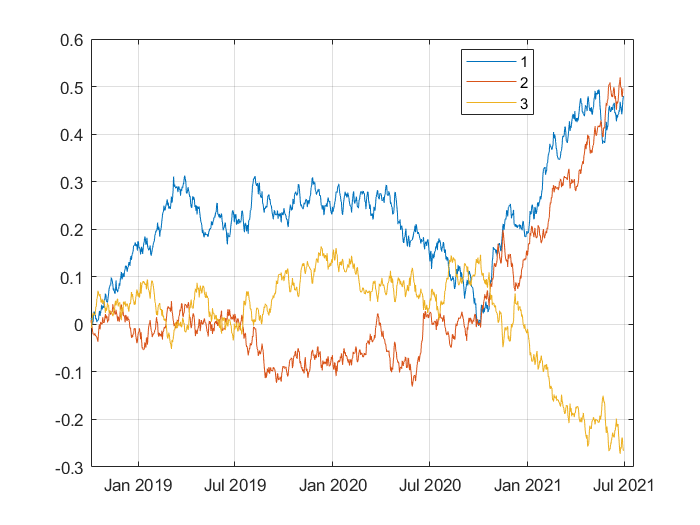

tf.cumsum().plot()  % applies a cumulative sum and then plot the result

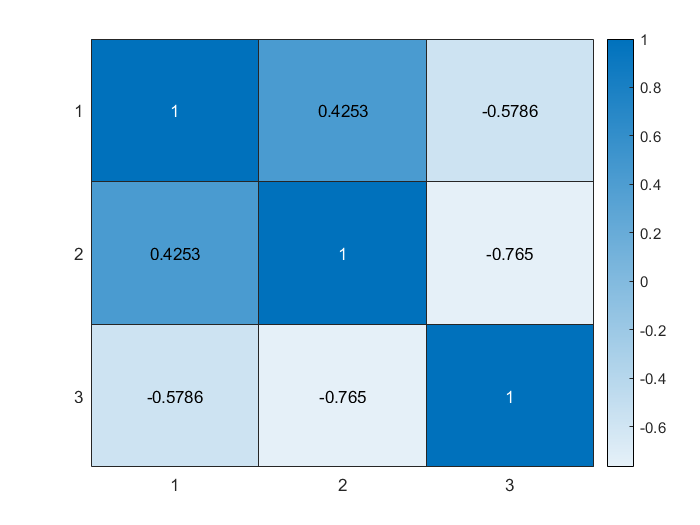

tf.corr().heatmap()  % computes the correlation matrix and plot it as a heatmap

## Rolling and Ewm

Computation on a rolling basis are available with the *.rolling()* and the *.ewm()* methods. *.rolling()* applies computations on a rolling window basis. *.ewm()* applies computations by weighting observations with exponentially decaying weights.

Please refer to the documentation for details on arguments and methods.

doc frames.DataFrame.rolling
% or 
doc frames.internal.Rolling

doc frames.DataFrame.ewm
% or
doc frames.internal.ExponentiallyWeightedMoving

Below, we give a few examples on how these methods can be used, using our previous TimeFrame.

price = tf.compoundChange('log');  % assume tf contains log returns and compound them
rollingMean = price.rolling(30).mean();  % 30-day moving average
exponentialMean = price.ewm(Span=30).mean();  % 30-day exponentially moving average
priceSmoothers = [price{:,1}, rollingMean{:,1}, exponentialMean{:,1}];  % group the first series

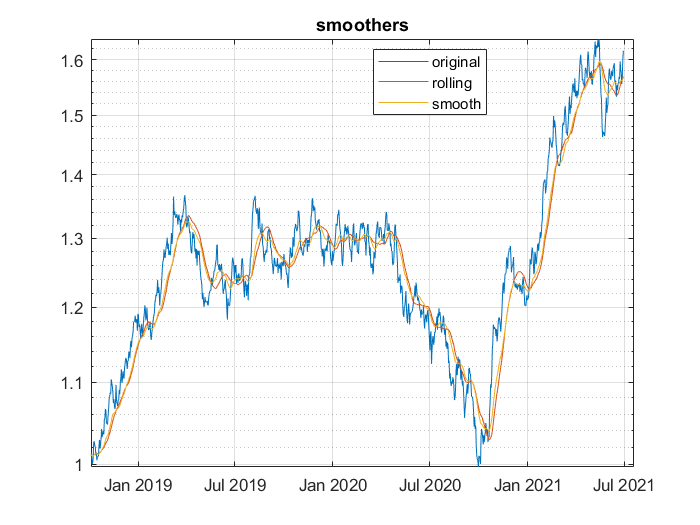

priceSmoothers.columns = ["original", "rolling", "smooth"];  % assign new column names
priceSmoothers.name = "smoothers";  % assign the name (it appears as the plot title)
priceSmoothers.plot(Log=true)

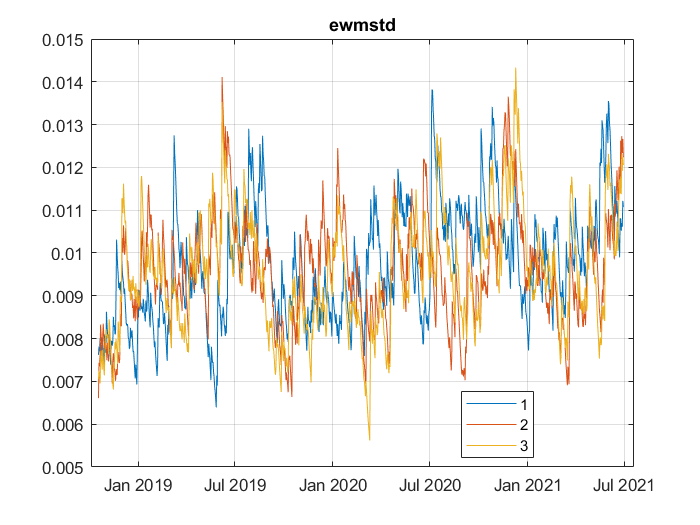

tf.ewm(Halflife=10).std().plot(Title='ewmstd')  % exponentially weighted moving standard deviation

## Split Apply

One can apply a function to groups of columns in a Frame using the method *.split(groups).apply(@<function>)*.

df = frames.DataFrame([1 2 3;2 5 3;5 0 1]',[],["a" "b" "c"])

df =          a    b    c
         _    _    _

    1    1    2    5
    2    2    5    0
    3    3    3    1


% simple example with cell
% apply a sum horizontally in each group
x1 = df.split({["a" "c"],"b"},["group1","group2"]).apply(@(x) x.sum(2))

x1 =          group1    group2
         ______    ______

    1      6         2   
    2      2         5   
    3      4         3   


% apply function using group names
% multiply each group by 10 and 1 respectively
multiplier.group1 = 10;
multiplier.group2 = 1;
x2 = df.split({["a" "c"],"b"},["group1","group2"]).apply(@(x) x.*multiplier.(x.name))

x2 =          a     c     b
         __    __    _

    1    10    50    2
    2    20     0    5
    3    30    10    3


% split with a structure
% cap each group at 1.5 and 2.5 respectively
s = struct();
s.group1 = ["a" "c"];
s.group2 = "b";
ceiler.group1 = 1.5;
ceiler.group2 = 2.5;
x3 = df.split(s).apply(@(x) x.clip(ceiler.(x.name)))

x3 =           a      c      b 
         ___    ___    ___

    1      1    1.5      2
    2    1.5      0    2.5
    3    1.5      1    2.5


% split with a Group
% take the maximum of each groups at each row
g = frames.Groups(df.columns,s);
x4 = df.split(g).apply(@(x) x.max(2))

x4 =          group1    group2
         ______    ______

    1      5         2   
    2      2         5   
    3      3         3   
